Load csv spreadsheet with all the data and show contents

Xall = readtable('Xall_figures.csv')

Xall = 2555×36 table
    Var1    participant_id    session_num    instance_num    attempt_num    treatment_cat    sahni_k      alpha       v_w_corr_pearson    mzn_props    attempt_submitted    time_on_task    length_of_sequence    num_unique_sets_in_seq    attempt_value    attempt_weight    solution_value    capacity    attempt_value_pct_solution    attempt_correct    len_sp_to_sol    ln_sp_first_tn_to_sol    ln_sp_last_tn_to_sol    num_items_overlap_first_tn_sol_set    num_items_overlap_last_tn_sol_set    alpha_attempt_set    mzn_props_attempt

Table S1

modelspec = 'attempt_correct ~ sahni_k + Complexity + Drug + (1|participant_id)'; 
mdl = fitglme(Xall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           4
    Random effects coefficients         40
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + sahni_k + Complexity + Drug + (1 | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11352    11381    -5670.9          11342   

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE          tStat      DF      pValue        Lower         Upper     
    {'(Intercept)'}            1.5811     0.22399     7.0591    2551    2.1518e-12        1.1419        2.0204
    {'sahni_k'    }          -0.53551     0.03598    -14.884    2551  

Table S2

modelspec = 'attempt_value_pct_solution ~ sahni_k + Complexity + mzn_props + Drug + (1|participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           5
    Random effects coefficients         40
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    attempt_value_pct_solution ~ 1 + sahni_k + mzn_props + Complexity + Drug + (1 | participant_id)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -10133    -10092    5073.5           -10147  

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE            tStat      DF      pValue        Lower          Upper      
    {'(Intercept)'}            0.96745     0.0034085     283.84    2550             0        0.96077        0.97414
    {'sahni_k'    }          0.00

Table S3

modelspec = 'time_on_task ~ sahni_k + Complexity + mzn_props + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    time_on_task ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    27232    27337    -13598           27196   

Fixed effects coefficients (95% CIs):
    Name                         Estimate      SE            tStat     DF      pValue        Lower         Upper     
    {'(Intercept)'      }            69.627          7.28    9.5642    2548     2.565e-21        55.352        83.903
    {'treatment_cat_DE

Table S4

modelspec = 'length_of_sequence ~ sahni_k + Complexity + mzn_props + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    length_of_sequence ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    21159    21264    -10562           21123   

Fixed effects coefficients (95% CIs):
    Name                         Estimate       SE            tStat      DF      pValue        Lower          Upper     
    {'(Intercept)'      }             4.1251        1.9983     2.0643    2548      0.039091        0.20661        8.0435
    {'trea

Table S5

modelspec = 'speed ~ sahni_k + Complexity + mzn_props + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    speed ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    14006    14112    -6985.2          13970   

Fixed effects coefficients (95% CIs):
    Name                         Estimate      SE            tStat       DF      pValue        Lower         Upper     
    {'(Intercept)'      }            9.7137       0.46524      20.879    2548    1.7054e-89        8.8014        10.626
    {'treatment_cat_DEX'}

Table S6

modelspec = 'productivity ~ 1 + sahni_k + Complexity + mzn_props + treatment_cat + (1 + treatment_cat|participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    productivity ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -9279.6    -9174.4    4657.8           -9315.6 

Fixed effects coefficients (95% CIs):
    Name                         Estimate       SE            tStat      DF      pValue         Lower          Upper      
    {'(Intercept)'      }            0.12712     0.0049474     25.695    2548    1.1381e-129        0.11742        0.13683
    

Table S7

modelspec = 'num_items_overlap_first_tn_sol_set ~ 1 + sahni_k + Drug + sahni_k*num_items_overlap_GA_sol + (1|participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           5
    Random effects coefficients         40
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    num_items_overlap_first_tn_sol_set ~ 1 + Drug + sahni_k*num_items_overlap_GA_sol + (1 | participant_id)

Model fit statistics:
    AIC     BIC       LogLikelihood    Deviance
    8602    8642.9    -4294            8588    

Fixed effects coefficients (95% CIs):
    Name                                        Estimate    SE          tStat      DF      pValue         Lower      Upper    
    {'(Intercept)'                     }           2.053     0.13819     14.856    2550     6.0347e-48     1.7821        2.324
    {'s

Fig S1

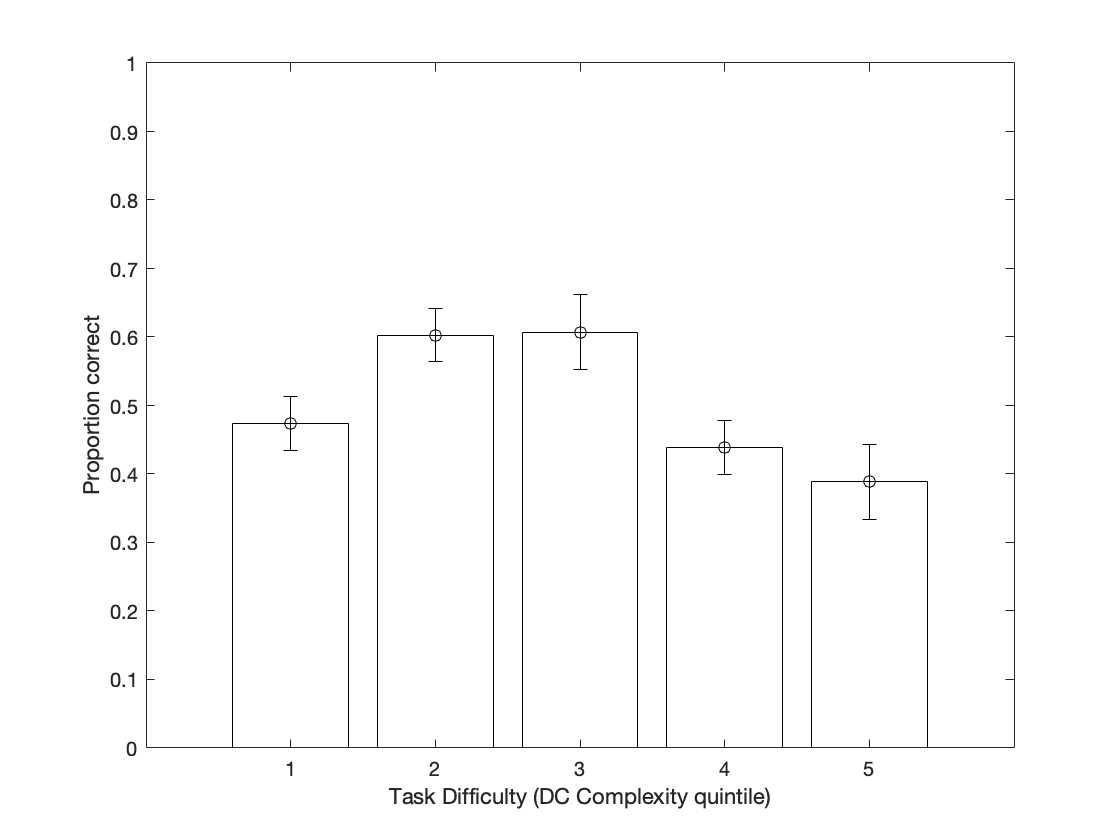

figure;
quint1 = prctile(Xall.Complexity,20);
fs = find(Xall.Complexity<=quint1);
solf0 = Xall.attempt_correct(fs);
quint2 = prctile(Xall.Complexity,40);
fs = find(Xall.Complexity>quint1 & Xall.Complexity<=quint2);
solf1 = Xall.attempt_correct(fs);
quint3 = prctile(Xall.Complexity,60);
fs = find(Xall.Complexity>quint2 & Xall.Complexity<=quint3);
solf2 = Xall.attempt_correct(fs);
quint4 = prctile(Xall.Complexity,80);
fs = find(Xall.Complexity>quint3 & Xall.Complexity<=quint4);
solf3 = Xall.attempt_correct(fs);
quint5 = prctile(Xall.Complexity,100); % superfluous; included for readability
fs = find(Xall.Complexity>quint4 & Xall.Complexity<=quint5);
solf4 = Xall.attempt_correct(fs);
mnsolf = [mean(solf0) mean(solf1) mean(solf2) mean(solf3) mean(solf4)];
mnx = 1:1:5;
ste = mnsolf.*(1-mnsolf); % standard error computations
ste = ste./[length(solf0) length(solf1) length(solf2) length(solf3) length(solf4)];
ste = sqrt(ste);
bar(mnx,mnsolf,'w')
axis([0 6 0 1])
xlabel('Task Difficulty (DC Complexity quintile)')
ylabel('Proportion correct')
hold on;
% error bars (=/- 2 s.e.) 
errorbar(mnx,mnsolf,2.*ste,'ok')
hold off;

Fig S2

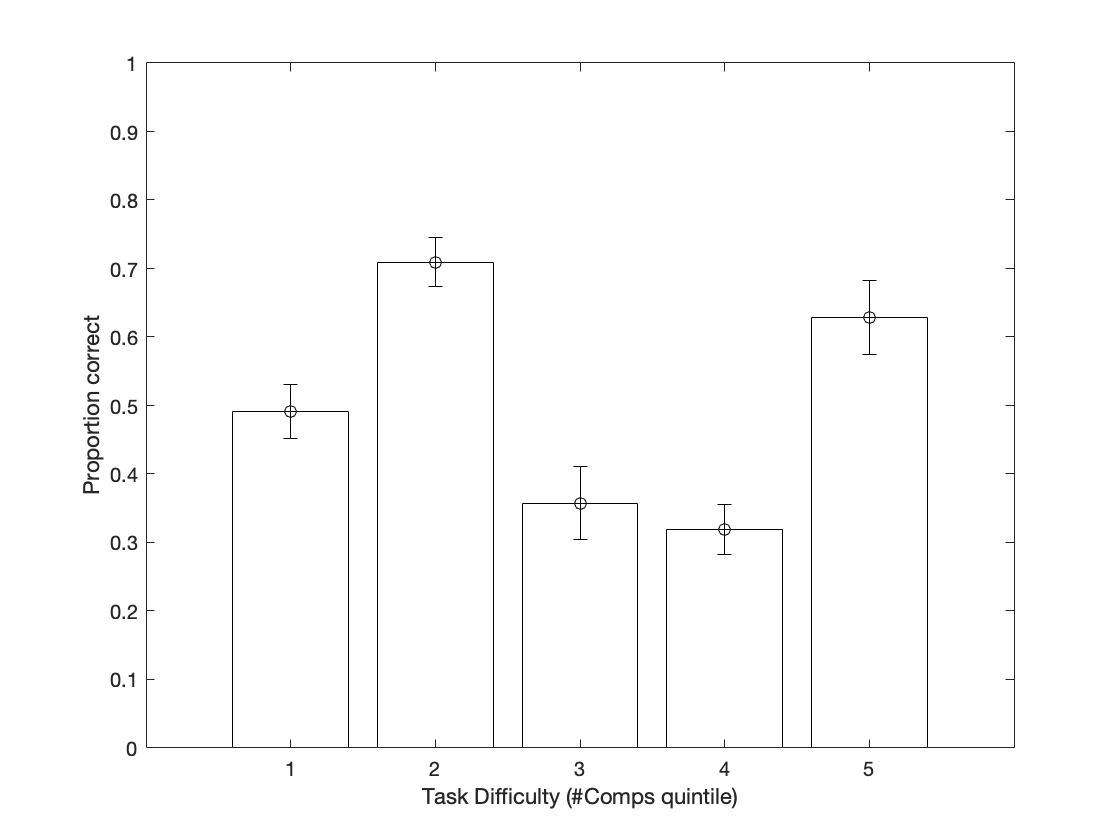

figure;
quint1 = prctile(Xall.mzn_props,20);
fs = find(Xall.mzn_props<=quint1);
solf0 = Xall.attempt_correct(fs);
quint2 = prctile(Xall.mzn_props,40);
fs = find(Xall.mzn_props>quint1 & Xall.mzn_props<=quint2);
solf1 = Xall.attempt_correct(fs);
quint3 = prctile(Xall.mzn_props,60);
fs = find(Xall.mzn_props>quint2 & Xall.mzn_props<=quint3);
solf2 = Xall.attempt_correct(fs);
quint4 = prctile(Xall.mzn_props,80);
fs = find(Xall.mzn_props>quint3 & Xall.mzn_props<=quint4);
solf3 = Xall.attempt_correct(fs);
quint5 = prctile(Xall.mzn_props,100); % superfluous; included for readability
fs = find(Xall.mzn_props>quint4 & Xall.mzn_props<=quint5);
solf4 = Xall.attempt_correct(fs);
mnsolf = [mean(solf0) mean(solf1) mean(solf2) mean(solf3) mean(solf4)];
mnx = 1:1:5;
ste = mnsolf.*(1-mnsolf); % standard error computations
ste = ste./[length(solf0) length(solf1) length(solf2) length(solf3) length(solf4)];
ste = sqrt(ste);
bar(mnx,mnsolf,'w')
axis([0 6 0 1])
xlabel('Task Difficulty (#Comps quintile)')
ylabel('Proportion correct')
hold on;
% error bars (=/- 2 s.e.) 
errorbar(mnx,mnsolf,2.*ste,'ok')
hold off;

Fig S3: Regression to mean of individual deviations from mean performance (score) under drugs vs PLC (with random effects for Drugs, slightly higher AIC and BIC than without)

modelspec = 'attempt_correct ~ sahni_k + Complexity + Drug + (1 + Drug|participant_id)'; 
mdl = fitglme(Xall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           4
    Random effects coefficients         80
    Covariance parameters                3
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + sahni_k + Complexity + Drug + (1 + Drug | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11372    11413    -5679            11358   

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE          tStat      DF      pValue        Lower         Upper     
    {'(Intercept)'}            1.5873     0.22491     7.0573    2551    2.1783e-12        1.1463        2.0283
    {'sahni_k'    }           -0.5383    0.036077    -14.921   

% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl);
psi{1,1} % or stats{1,1}

ans =     0.5121   -0.1060
   -0.1060    0.2680


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl);
% intercept and slopes
% Association random effects PLC against Drug
figure;
p1 = plot(B(1:2:end),B(2:2:end),'ob')

p1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.2709 -0.1477 0.3345 1.1587 -0.1213 1.1987 0.0642 -0.2412 -1.2864 -0.0157 -0.1324 0.3345 -0.7127 0.4297 -0.7566 -1.3114 0.2008 -0.0293 0.7272 -0.0293 -0.4360 0.0148 -0.2437 0.8165 -0.4194 1.1587 0.1401 0.0902 1.1917 -0.0022 … ]
              YData: [0.3642 -0.0707 0.0280 -0.0975 0.5896 -0.0489 -0.3725 0.4088 -0.4579 0.4383 -0.3578 0.0280 0.0193 -0.4542 0.1954 0.0302 -0.4790 0.1077 -0.3464 0.1077 -0.1936 0.4842 0.0949 0.3948 0.1413 -0.0975 -0.5693 0.2870 0.5630 -0.6704 … ]

  Show all properties


xlabel('Deviation from mean performance under PLC')
ylabel('Deviation from mean performance under Drugs')
axis([-1.5 1.5 -1.5 1.5])
hold on;
bigX = [ones(length(B(1:2:end)),1), B(1:2:end)];
[b bint] = regress(B(2:2:end),bigX,0.1)

b =    -0.0000
    0.0064


bint =    -0.0918    0.0918
   -0.1444    0.1572


Bhat = bigX*b;
p2 = plot(B(1:2:end),Bhat,'-r')

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.2709 -0.1477 0.3345 1.1587 -0.1213 1.1987 0.0642 -0.2412 -1.2864 -0.0157 -0.1324 0.3345 -0.7127 0.4297 -0.7566 -1.3114 0.2008 -0.0293 0.7272 -0.0293 -0.4360 0.0148 -0.2437 0.8165 -0.4194 1.1587 0.1401 0.0902 1.1917 -0.0022 … ]
              YData: [-0.0017 -9.3860e-04 0.0021 0.0074 -7.7046e-04 0.0076 4.0759e-04 -0.0015 -0.0082 -9.9887e-05 -8.4111e-04 0.0021 -0.0045 0.0027 -0.0048 -0.0083 0.0013 -1.8626e-04 0.0046 -1.8626e-04 -0.0028 9.3843e-05 -0.0015 0.0052 -0.0027 0.0074 … ]

  Show <a href="matlab:if exist('p2', 'var'), matlab.graphics.internal.getForDisplay('p2', p2, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p2'), end">all properties<

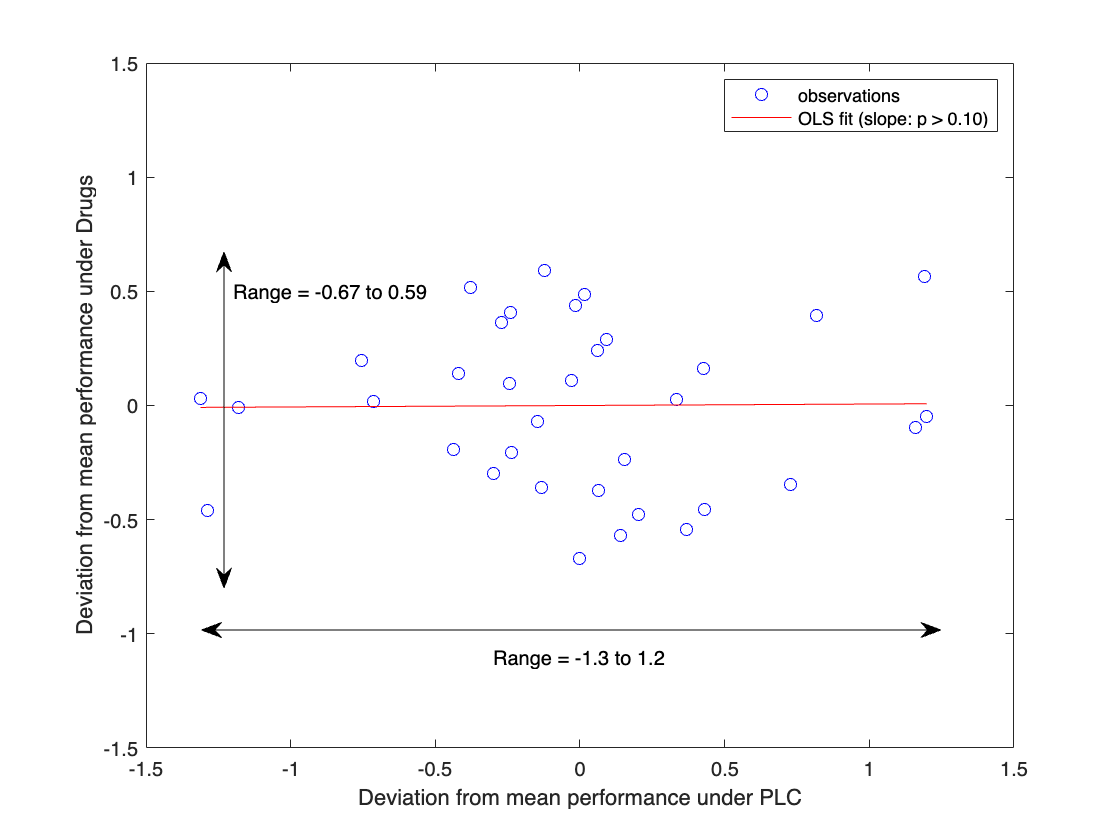

%legend('Individuals','OLS Fit (p < 0.001)')
ymin = min(B(2:2:end));
ymax = max(B(2:2:end));
annotation('doublearrow',[0.2,0.2],[0.3,0.7])
ymin = num2str(ymin,2);
ymax = num2str(ymax,2);
tkst = ['Range = ', ymin, ' to ', ymax];
text(-1.2,0.5,tkst)
ymin = min(B(1:2:end));
ymax = max(B(1:2:end));
annotation('doublearrow',[0.18,0.84],[0.25,0.25])
ymin = num2str(ymin,2);
ymax = num2str(ymax,2);
tkst = ['Range = ', ymin, ' to ', ymax];
text(-0.3,-1.1,tkst)
legend('observations','OLS fit (slope: p > 0.10)')
hold off;

Wilcoxon signed-rank statistic for paired differences of SQUARES

y2 = B(2:2:end).^2;
x2 = B(1:2:end).^2;
diffyx = y2-x2;
p = signrank(diffyx)

p = 0.7882

Fig S4: Negative correlation of individual deviations from mean productivity under MOD vs PLC (Analogouus to Fig 3b in Figures.mlx)

modelspec = 'productivity ~ 1 + treatment_cat + sahni_k + Complexity + mzn_props + (1 + treatment_cat | participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    productivity ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -9279.6    -9174.4    4657.8           -9315.6 

Fixed effects coefficients (95% CIs):
    Name                         Estimate       SE            tStat      DF      pValue         Lower          Upper      
    {'(Intercept)'      }            0.12712     0.0049474     25.695    2548    1.1381e-129        0.11742        0.13683
    


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl);
psi{1,1} % or stats{1,1}

ans = 1.0e-03 *

    0.5315   -0.0740   -0.0758   -0.2242
   -0.0740    0.2307   -0.0582    0.1872
   -0.0758   -0.0582    0.0599    0.0056
   -0.2242    0.1872    0.0056    0.3104


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl);
% intercept and slopes
% Association random effects DEX against MPH
figure;
plot(B(1:4:end),B(4:4:end),'ob')
xlabel('Deviation from mean productivity under PLC')
ylabel('Deviation from mean productivity under MOD')
%axis([-0.025 0.035 -0.025 0.035])
hold on;
bigX = [ones(length(B(4:4:end)),1), B(1:4:end)];
[b bint] = regress(B(4:4:end),bigX,0.001)

b =     0.0000
   -0.3762


bint =    -0.0071    0.0071
   -0.6949   -0.0576


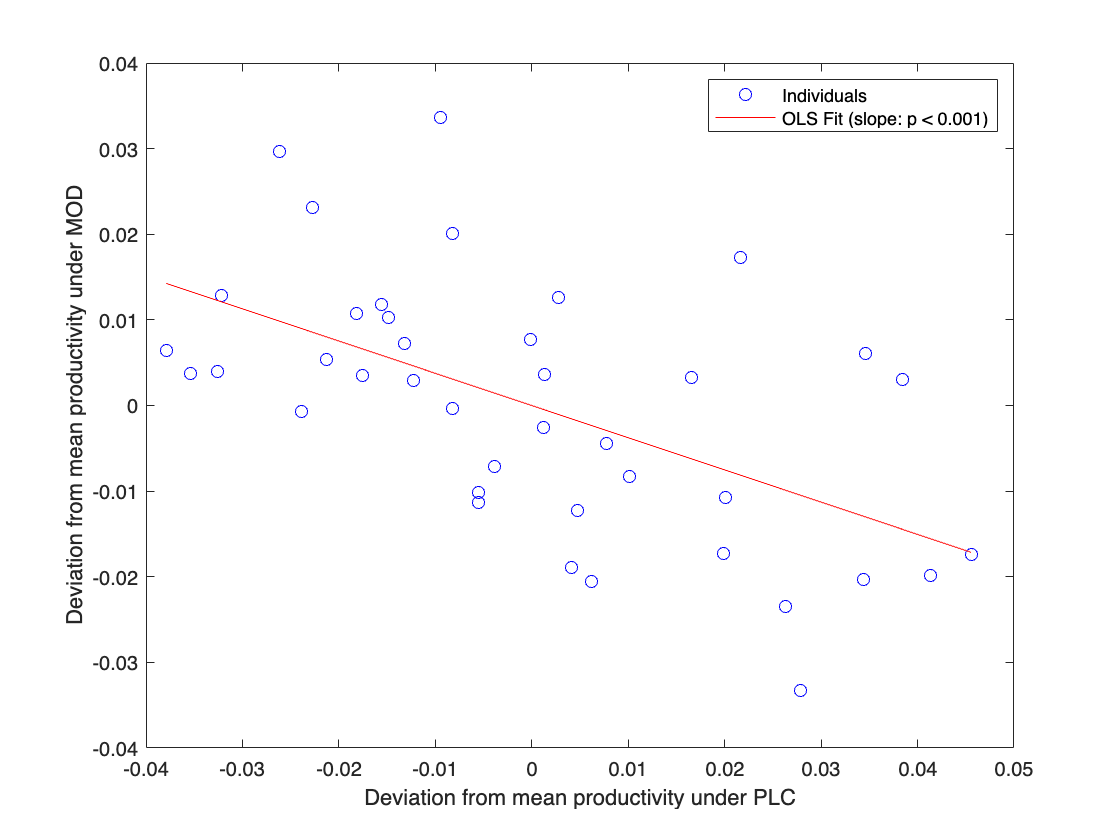

Bhat = bigX*b;
plot(B(1:4:end),Bhat,'-r')
legend('Individuals','OLS Fit (slope: p < 0.001)')
hold off;

% Pro Memoria, standard error correlation; critical value 95, 99%
secorr = 1/sqrt(160)

secorr = 0.0791

crit01 = 2.3263/sqrt(160)

crit01 = 0.1839

crit001 = 3.1./sqrt(160)

crit001 = 0.2451

Wilcoxon signed-rank statistic for paired differences of SQUARES

y2 = B(4:4:end).^2;
x2 = B(1:4:end).^2;
diffyx = y2-x2;
p = signrank(diffyx)

p = 0.0155

Fig S5: Negative but insignificant correlation of individual deviations from mean productivity under DEX vs PLC (Analogous to Fig 3b in Figures.mlx)

modelspec = 'productivity ~ 1 + treatment_cat + sahni_k + Complexity + mzn_props + (1 + treatment_cat | participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    productivity ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -9279.6    -9174.4    4657.8           -9315.6 

Fixed effects coefficients (95% CIs):
    Name                         Estimate       SE            tStat      DF      pValue         Lower          Upper      
    {'(Intercept)'      }            0.12712     0.0049474     25.695    2548    1.1381e-129        0.11742        0.13683
    


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl);
psi{1,1} % or stats{1,1}

ans = 1.0e-03 *

    0.5315   -0.0740   -0.0758   -0.2242
   -0.0740    0.2307   -0.0582    0.1872
   -0.0758   -0.0582    0.0599    0.0056
   -0.2242    0.1872    0.0056    0.3104


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl);
% intercept and slopes
% Association random effects DEX against MPH
figure;
plot(B(1:4:end),B(2:4:end),'ob')
xlabel('Deviation from mean productivity under PLC')
ylabel('Deviation from mean productivity under DEX')
%axis([-0.025 0.035 -0.025 0.035])
hold on;
bigX = [ones(length(B(2:4:end)),1), B(1:4:end)];
[b bint] = regress(B(2:4:end),bigX,0.05)

b =     0.0000
   -0.1011


bint =    -0.0042    0.0042
   -0.2889    0.0868


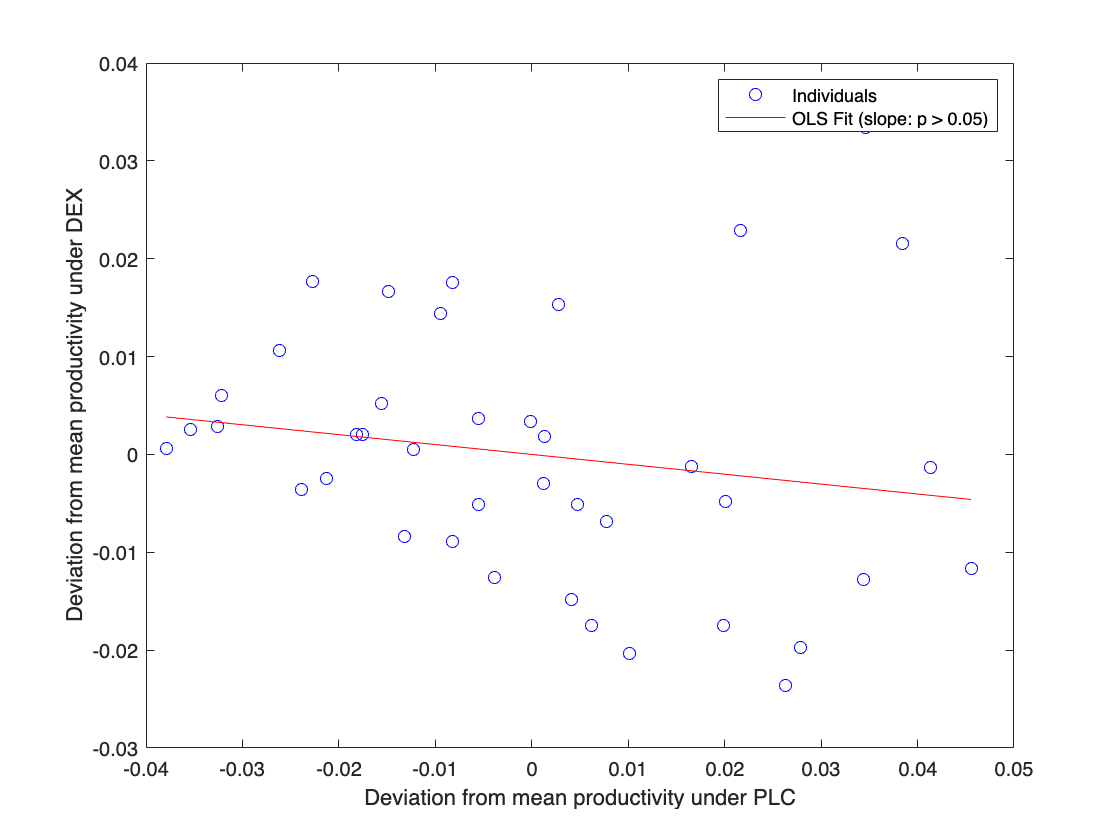

Bhat = bigX*b;
plot(B(1:4:end),Bhat,'-r')
legend('Individuals','OLS Fit (slope: p > 0.05)')
hold off;

Wilcoxon signed-rank statistic for paired differences of SQUARES

y2 = B(2:4:end).^2;
x2 = B(1:4:end).^2;
diffyx = y2-x2;
p = signrank(diffyx)

p = 0.0017

Fig S6: Negative correlation of individual deviations from mean productivity under MPH vs DEX (Analogous to as Fig 3c in Figures.mlx)

modelspec = 'productivity ~ 1 + treatment_cat + sahni_k + Complexity + mzn_props + (1 + treatment_cat | participant_id)';
mdl = fitglme(Xall,modelspec,'Distribution','normal','Link','identity')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           7
    Random effects coefficients        160
    Covariance parameters               11
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    productivity ~ 1 + treatment_cat + sahni_k + mzn_props + Complexity + (1 + treatment_cat | participant_id)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -9279.6    -9174.4    4657.8           -9315.6 

Fixed effects coefficients (95% CIs):
    Name                         Estimate       SE            tStat      DF      pValue         Lower          Upper      
    {'(Intercept)'      }            0.12712     0.0049474     25.695    2548    1.1381e-129        0.11742        0.13683
    


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl);
psi{1,1} % or stats{1,1}

ans = 	1.0e+-3 *

    0.5315   -0.0740   -0.0758   -0.2242
   -0.0740    0.2307   -0.0582    0.1872
   -0.0758   -0.0582    0.0599    0.0056
   -0.2242    0.1872    0.0056    0.3104


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl);
% intercept and slopes
% Association random effects DEX against MPH
figure;
plot(B(2:4:end),B(3:4:end),'ob')
xlabel('Deviation from mean productivity under DEX')
ylabel('Deviation from mean productivity under MPH')
axis([-0.025 0.035 -0.025 0.035])
hold on;
bigX = [ones(length(B(2:4:end)),1), B(2:4:end)];
[b bint] = regress(B(3:4:end),bigX,0.0001)

b =    -0.0000
   -0.2937


bint =    -0.0031    0.0031
   -0.5321   -0.0554


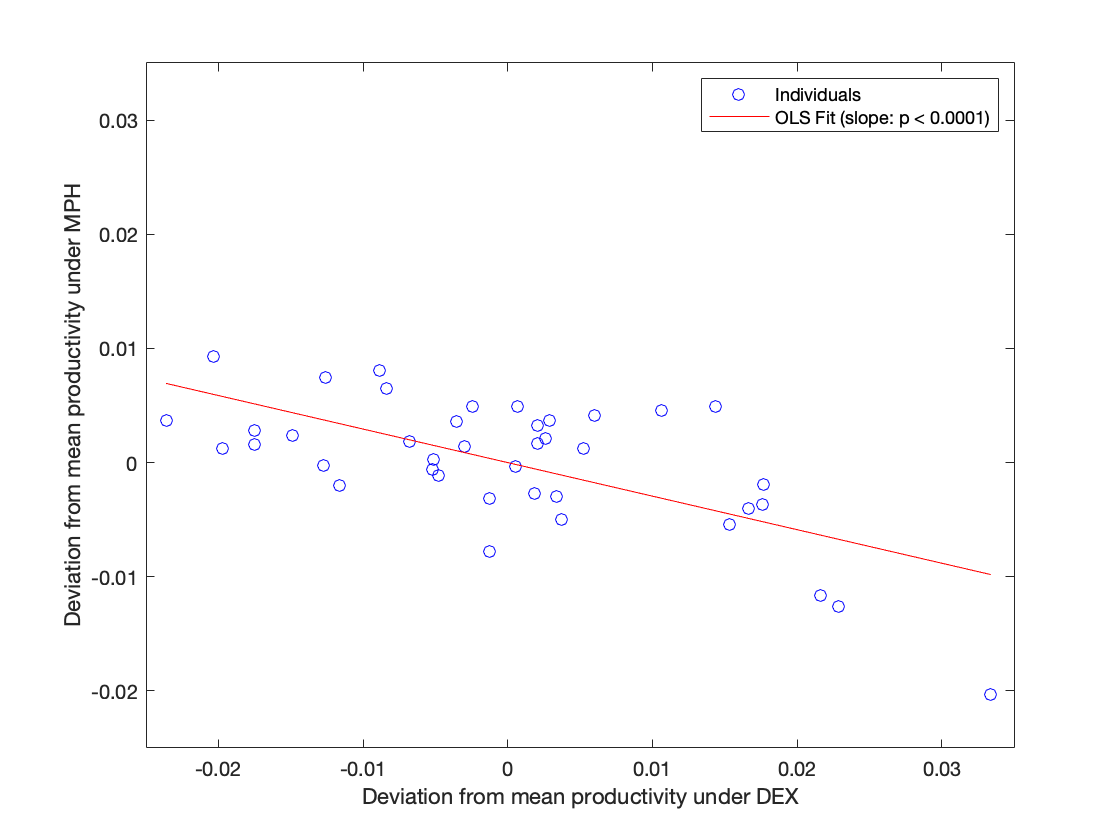

Bhat = bigX*b;
plot(B(2:4:end),Bhat,'-r')
legend('Individuals','OLS Fit (slope: p < 0.0001)')
hold off;

The following uses CANTAB data and merge them with the KS data. 

Fig S7: CANTAB Spatial Working Memory task (SWMSX); run glmfit of Table 1, then correlate performance random effects (per participant) against score on SMWSX

Yall=readtable('PECO_CANTAB_data_PB_SWMSX.csv');

Zall=outerjoin(Xall,Yall,'LeftKeys',[2 3],'RightKeys',[2,3]);

% Means per participants (categorical)
rows = (Zall.Drug_Xall==1)|(Zall.Drug_Xall==0); % pick all rows - unless drug effect is needed
xbar =  grpstats(Zall.SWMSX(rows),Zall.participant(rows),{'mean'});
modelspec = 'attempt_correct ~ sahni_k + Complexity + Drug_Xall + (1|participant_id)';
mdl = fitglme(Zall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           4
    Random effects coefficients         40
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + sahni_k + Complexity + Drug_Xall + (1 | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11352    11381    -5670.9          11342   

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE          tStat      DF      pValue        Lower         Upper     
    {'(Intercept)'}            1.5811     0.22399     7.0591    2551    2.1518e-12        1.1419        2.0204
    {'sahni_k'    }          -0.53551     0.03598    -14.884    2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl,'Alpha',0.01);
stats{1,1} % psi{1,1} 

ans =     Covariance Type: Isotropic

    Group          Name1                  Name2                  Type           Estimate    Lower      Upper  
    [1x14 char]    {'(Intercept)'}        {'(Intercept)'}        {'std'}        0.70672     0.70672    0.70672


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl,'Alpha',0.01);
% plot relation
plot(xbar,B,'or')
[BB BBint] = regress(B,[ones(size(xbar)) xbar],0.001)

BB =     0.7833
   -0.0824


BBint =    -0.0563    1.6230
   -0.1637   -0.0011


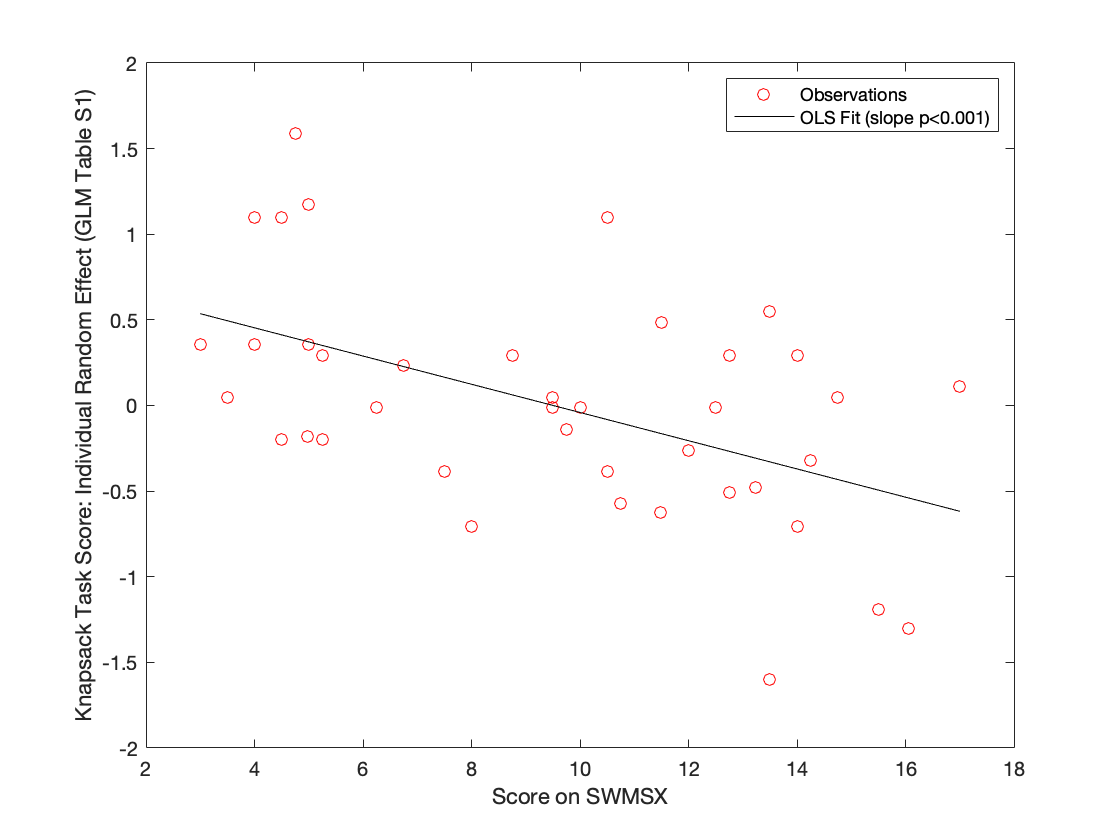

hold on;
plot(xbar,[ones(size(xbar)) xbar]*BB,'-k')
xlabel('Score on SWMSX')
ylabel('Knapsack Task Score: Individual Random Effect (GLM Table S1)')
legend('Observations','OLS Fit (slope p<0.001)')
hold off;

Fig S8: Same as Figure S7, for score on CANTAB Simple Reaction Time Task

Yall=readtable('PECO_CANTAB_reactiontime.csv'); 

Zall=outerjoin(Xall,Yall,'LeftKeys',[2 3],'RightKeys',[2,3]);

% Means per participants (categorical)
rows = (Zall.Drug_Xall==1)|(Zall.Drug_Xall==0); % pick all rows - unless drug effect is needed
xbar =  grpstats(Zall.RTISMRT(rows),Zall.participant(rows),{'mean'});

modelspec = 'attempt_correct ~ sahni_k + Complexity + Drug_Xall + (1|participant_id)';
mdl = fitglme(Zall,modelspec,'Distribution','binomial','Link','logit')

mdl = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            2555
    Fixed effects coefficients           4
    Random effects coefficients         40
    Covariance parameters                1
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    attempt_correct ~ 1 + sahni_k + Complexity + Drug_Xall + (1 | participant_id)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    11352    11381    -5670.9          11342   

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE          tStat      DF      pValue        Lower         Upper     
    {'(Intercept)'}            1.5811     0.22399     7.0591    2551    2.1518e-12        1.1419        2.0204
    {'sahni_k'    }          -0.53551     0.03598    -14.884    2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% To get full stats of covariance of random effects:
[psi,mse,stats]=covarianceParameters(mdl,'Alpha',0.01);
stats{1,1} % psi{1,1} 

ans =     Covariance Type: Isotropic

    Group          Name1                  Name2                  Type           Estimate    Lower      Upper  
    [1x14 char]    {'(Intercept)'}        {'(Intercept)'}        {'std'}        0.70672     0.70672    0.70672


% To get random coefficients, use
[B,BNames,statsB]=randomEffects(mdl,'Alpha',0.01);
% plot relation
plot(xbar,B,'or')
[BB BBint] = regress(B,[ones(size(xbar)) xbar],0.01)

BB =     3.4788
   -0.0099


BBint =     0.2319    6.7257
   -0.0191   -0.0007


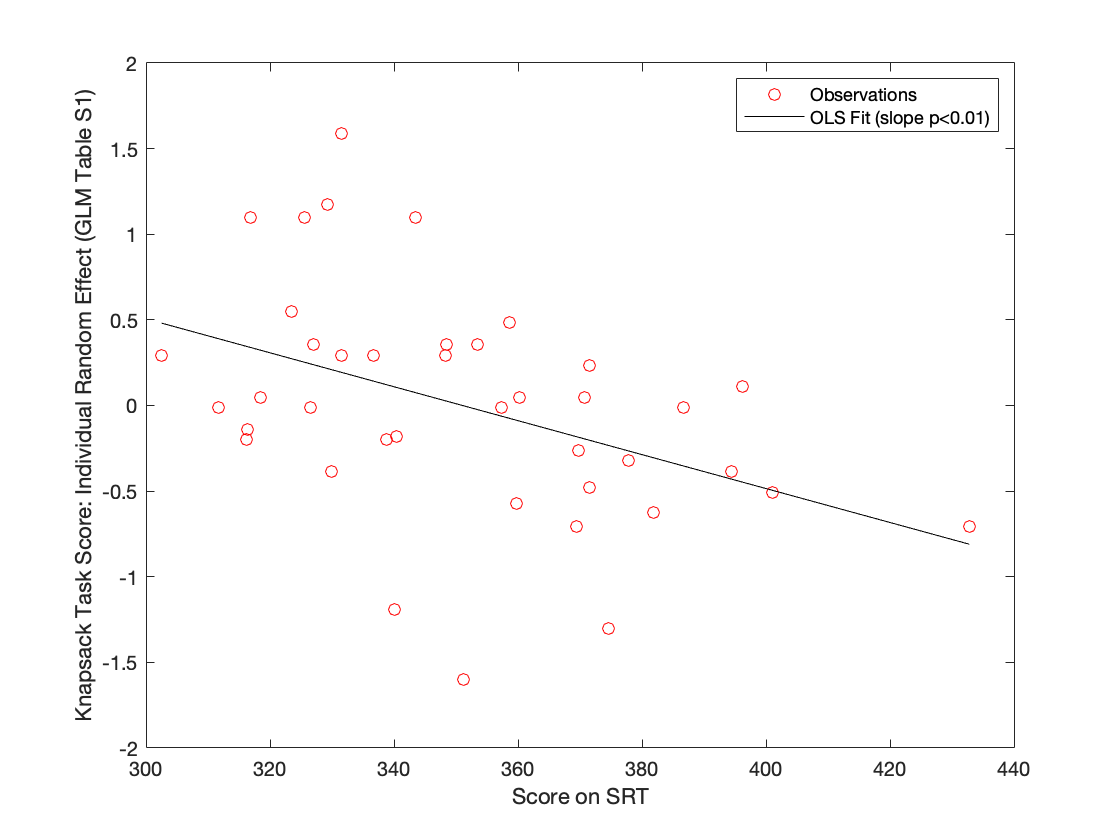

hold on;
plot(xbar,[ones(size(xbar)) xbar]*BB,'-k')
xlabel('Score on SRT')
ylabel('Knapsack Task Score: Individual Random Effect (GLM Table S1)')
legend('Observations','OLS Fit (slope p<0.01)')
hold off;